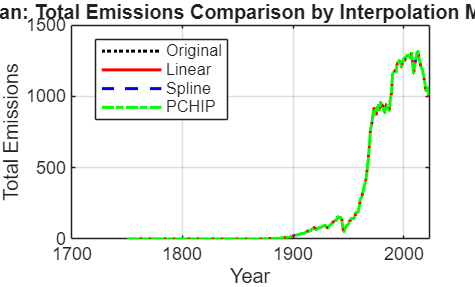

% Read the Excel file
data = readtable('carbon_emissions_full_data.xlsx', 'VariableNamingRule', 'preserve');

% Filter only Japan rows
japanData = data(strcmp(data.Country,'Japan'), :);

% Extract Flaring column
flaring = japanData.Flaring;

% Find the first and last real measurements (>0)
firstNonZero = find(flaring > 0, 1, 'first');   % first actual value
lastNonZero  = find(flaring > 0, 1, 'last');    % last actual value

% Step 1: Set all leading values (before first measurement) to 0
flaring(1:firstNonZero-1) = 0;

% Step 2: Set internal zeros (between first and last measurement) to NaN
internalIdx = firstNonZero:lastNonZero;
flaring(internalIdx(flaring(internalIdx)==0)) = NaN;

% Update the table
japanData.Flaring = flaring;

vars = {'Coal','Oil','Gas','Cement','Flaring','Other'};
japanData1.Total = sum(japanData1{:,vars},2,'omitnan');
japanData2.Total = sum(japanData2{:,vars},2,'omitnan');
japanData3.Total = sum(japanData3{:,vars},2,'omitnan');

figure;
plot(japanData.Year, japanData.Total, 'k:', 'LineWidth', 1.5); hold on; 
plot(japanData1.Year, japanData1.Total, 'r-', 'LineWidth', 1.5);
plot(japanData2.Year, japanData2.Total, 'b--', 'LineWidth', 1.5);%
plot(japanData3.Year, japanData3.Total, 'g-.', 'LineWidth', 1.5);
legend({'Original', 'Linear','Spline','PCHIP'}, 'Location', 'best');
xlabel('Year');
ylabel('Total Emissions');
title('Japan: Total Emissions Comparison by Interpolation Method');
grid on;